# 1D HEAT CONDUCTION IN A UNIFORM ROD WITH DIRICHLET'S BOUNDARY CONDITIONS (Separation of Variable)

## Heat Equation (One Dimension)

Heat equation is a *parabolic *partial differenital equaiton. This heat equation in one dimension is used to model the *temprature distribution *in a one dimensional rod. 

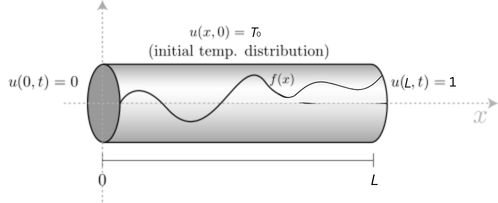

The equation is given by:

s$\frac{\partial u}{\partial t}\;=\;k\;\frac{\partial^2 u}{\partial x^2 }$

- $u\left(x,t\right)$is the temprature at position $x$ (spatial variable) and time $t\;$

- $\frac{\partial u}{\partial t}$ is the partial derivative with respect to time $t$

- $k$ is the rate of heat transfer in a material

- $\frac{\partial^2 u}{\partial x^2 }$ is the second partial derivaitve of u with respect ot spatial variable x

### **Initial & Boundary Conditions (IBCs)**

This equation describes the dissipation of heat for $0\le x\le L$ and $t\ge 0$. Our goal is to solve it for the temperature $u\left(x,t\right)$.

Initially the temperature is a nonzero constant, so the initial condition is


$$u\left(x,0\right)=T_0$$


Also, the temperature is zero at the left boundary, and nonzero at the right boundary, so the boundary conditions are


$$u\left(0,t\right)=0\;\;\;\;\;\;\;;\;\;\;\;\;\;\;\;u\left(L,t\right)=1$$


### Steps to Solve at Matlab

- Code the equation

- Initial conditions & boundary conditions

- Select a suitable solution mesh before calling the solver `pdepe`

## Code Equation

Before you can code the equation, you need to make sure that it is in the form that the `pdepe` solver expects:


$$c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t}=x^{-m} \frac{\partial }{\partial x}\left(x^m f\left(x,t,u,\frac{\partial u}{\partial x}\right)\right)+s\left(x,t,u,\frac{\partial u}{\partial x}\right)\ldotp$$


In this form, the heat equation is


$$1\cdot \frac{\partial u}{\partial t}=x^0 \frac{\partial }{\partial x}\left(x^0 \frac{\partial u}{\partial x}\right)+0\ldotp$$


So the values of the coefficients are as follows:

- 
$$m=0$$


- 
$$c=1$$


- 
$$f=\frac{\partial u}{\partial x}$$


- 
$$s=0$$


The value of $m$ is passed as an argument to `pdepe`, while the other coefficients are encoded in a function for the equation, which is

(Note: All functions are included as local functions at the end of the example.)

## Code Initial Condition

The initial condition function for the heat equation assigns a constant value for $u_0$. This function must accept an input for $x$, even if it is unused.

## Code Boundary Conditions

The standard form for the boundary conditions expected by the `pdepe` solver is


$$p\left(x,t,u\right)+q\left(x,t\right)f\left(x,t,u,\frac{\partial u}{\partial x}\right)=0\ldotp$$


Written in this form, the boundary conditions for this problem are


$$u\left(0,t\right)+\left(0\cdot f\right)=0,$$



$$\left(u\left(L,t\right)-1\right)+\left(0\cdot f\right)=0\ldotp$$


So the values for $p$ and $q$ are

- 
$$p_L =u_L ,{\;\;\;\;\;\;\;\;\;\;\;\;\;q}_L =0\ldotp$$


- $p_R =u_R -1,{\;\;\;\;\;q}_R =0$.

The corresponding function is then

## Select Solution Mesh

Use a spatial mesh of 20 points and a time mesh of 30 points. Since the solution rapidly reaches a steady state, the time points near $t=0$ are more closely spaced together to capture this behavior in the output. 

L = 1;
x = linspace(0,L,20);
t = [linspace(0,0.05,20), linspace(0.5,5,10)];

## Solve Equation

Finally, solve the equation using the symmetry $m$, the PDE equation, the initial condition, the boundary conditions, and the meshes for $x$ and $t$.

m = 0;
sol = pdepe(m,@heatpde,@heatic,@heatbc,x,t);

## Plot Solution

Use `imagesc` to visualize the solution matrix. 

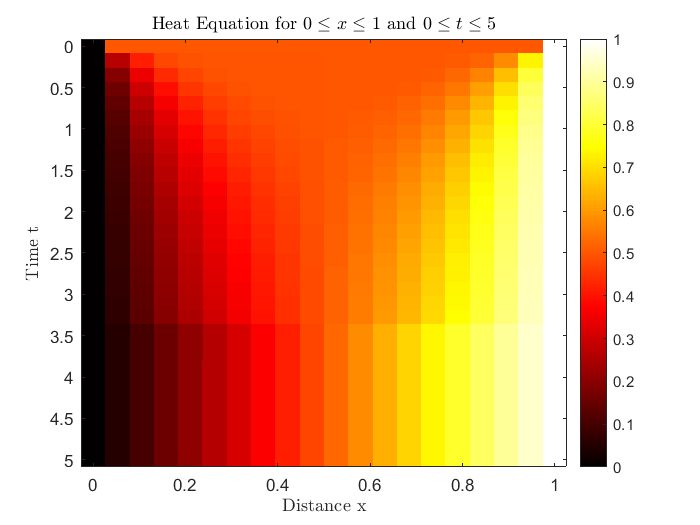

colormap hot
imagesc(x,t,sol)
colorbar
xlabel('Distance x','interpreter','latex')
ylabel('Time t','interpreter','latex')
title('Heat Equation for $0 \le x \le 1$ and $0 \le t \le 5$','interpreter','latex')